# Pseudo-Inverse Approximation

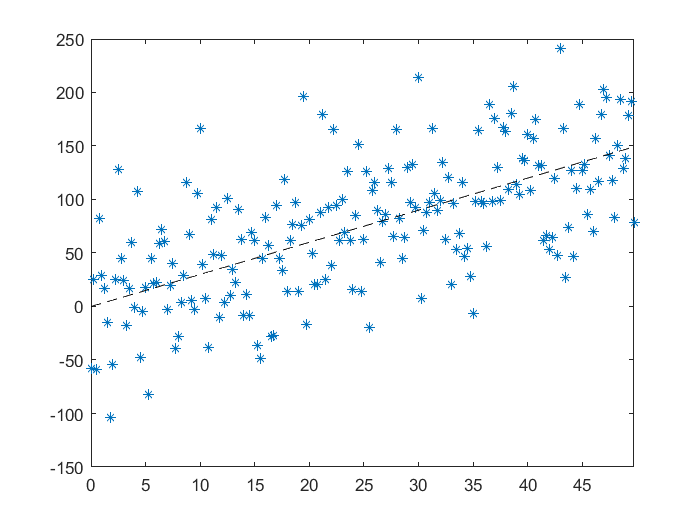

clear;clc;

m = 3;
dx = 0.25;
L = 50;
a = (0:dx:L-dx)';
b = m*a + L*randn(size(a));
figure(1);
plot(a,b,'*');
hold on;
plot(a,m*a,'k--');
xlim([0 L-dx]);

## Approximate m using Pseudo-Inverse

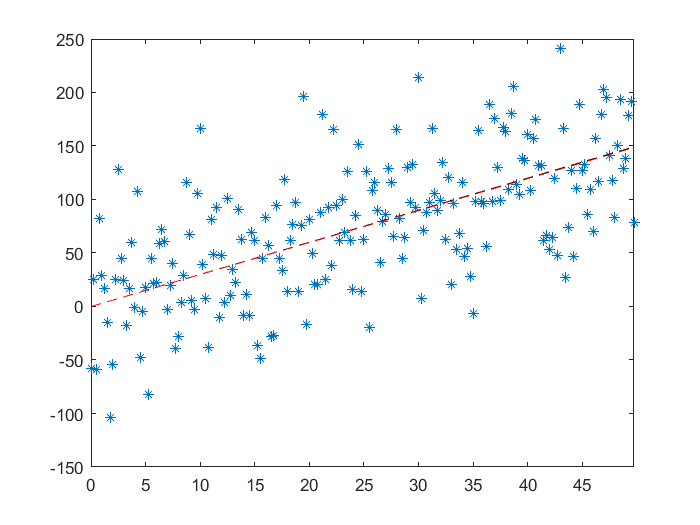

[U,S,V] = svd(a,'econ');
m_approx = V*inv(S)*U'*b;
plot(a,m_approx*a,'r--');